csv_data = '/Users/simonsymhoven/Uni/master/big-data-analytics/uebung01/big-data-hm-group-j/BDA_01/timesData.csv';
T = sortrows(readtable(csv_data))

T = 100×3 table
    AnzahlZeichen    ZeitNormal    ZeitParallel
    _____________    __________    ____________

         10000            1              2     
         20000            3              1     
         30000            4              2     
         40000            6              3     
         50000            8              4     
         60000            9              5     
         70000           11              6     
         80000           13              7     
         90000           14              8     
         1e+05           16              9     
       1.1e+05           18             10     
       1.2e+05           20             11     
       1.3e+05           21             12     
       1.4e+05           24             14     
       1.5e+05           25             15     
       1.6e+05           27             15     


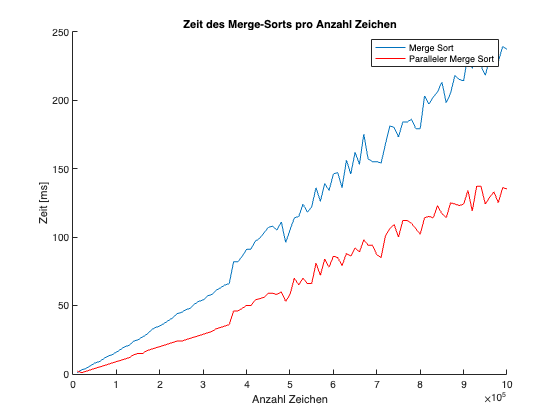



figure;
hold on;
plot(T.AnzahlZeichen, T.ZeitNormal)
plot(T.AnzahlZeichen, T.ZeitParallel, 'r')
xlabel('Anzahl Zeichen')
ylabel('Zeit [ms]')
legend('Merge Sort','Paralleler Merge Sort')

title('Zeit des Merge-Sorts pro Anzahl Zeichen')